clear ;
close all;


load ryan2_gen_data.mat

전체 데이타 셋의 discahrge Q 를 smooth해서 표시

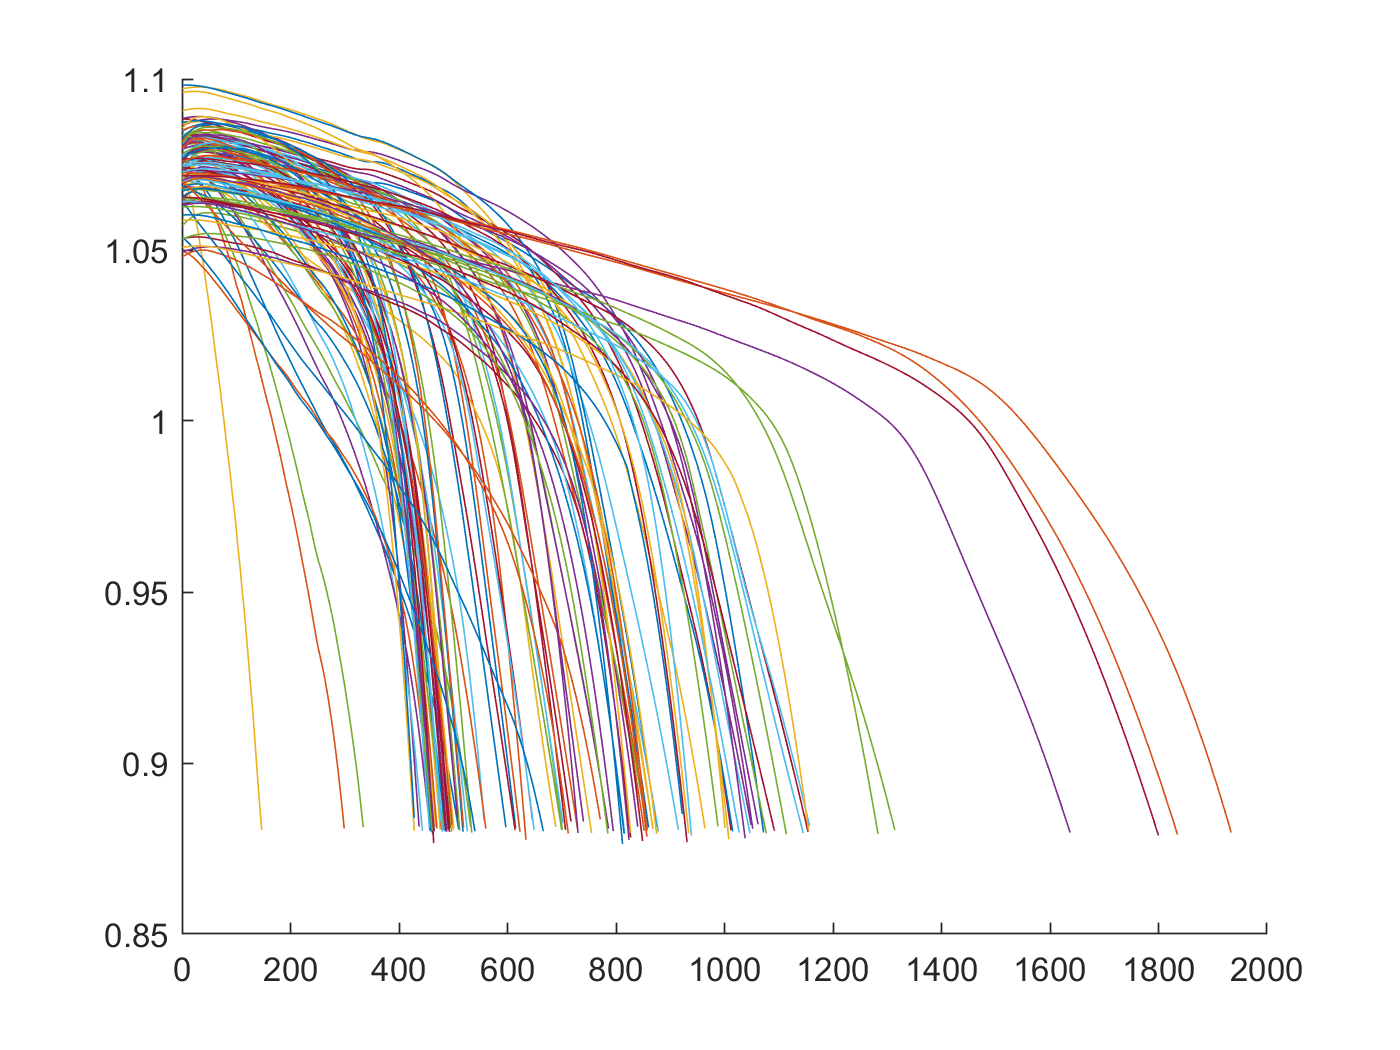

% here
figure
hold on
for i=1:length(idxAll)
    plot(battery_dataset(idxAll(i)).QDischargeSmooth)
end
hold off

batch 1,2 의 discharge Q 만 표시 = training set으로 사용할 예정

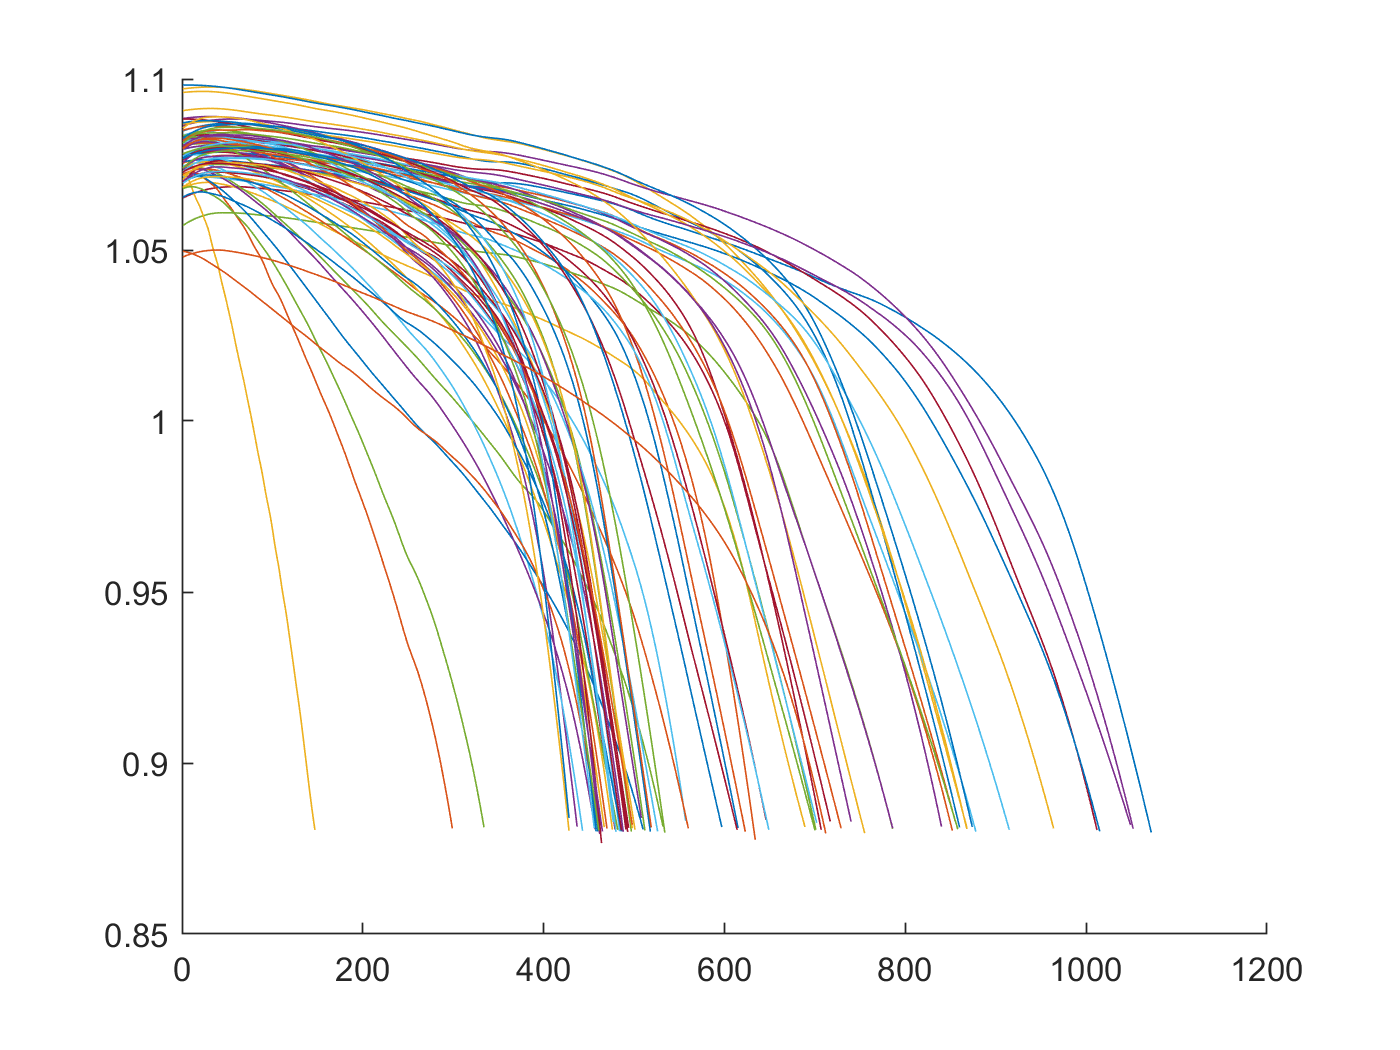

figure
hold on
for i=1:length(idx12)
    plot(battery_dataset(idx12(i)).QDischargeSmooth)
end
hold off

batch 3 의 discharge Q 만 표시 = test set으로 사용할 예정

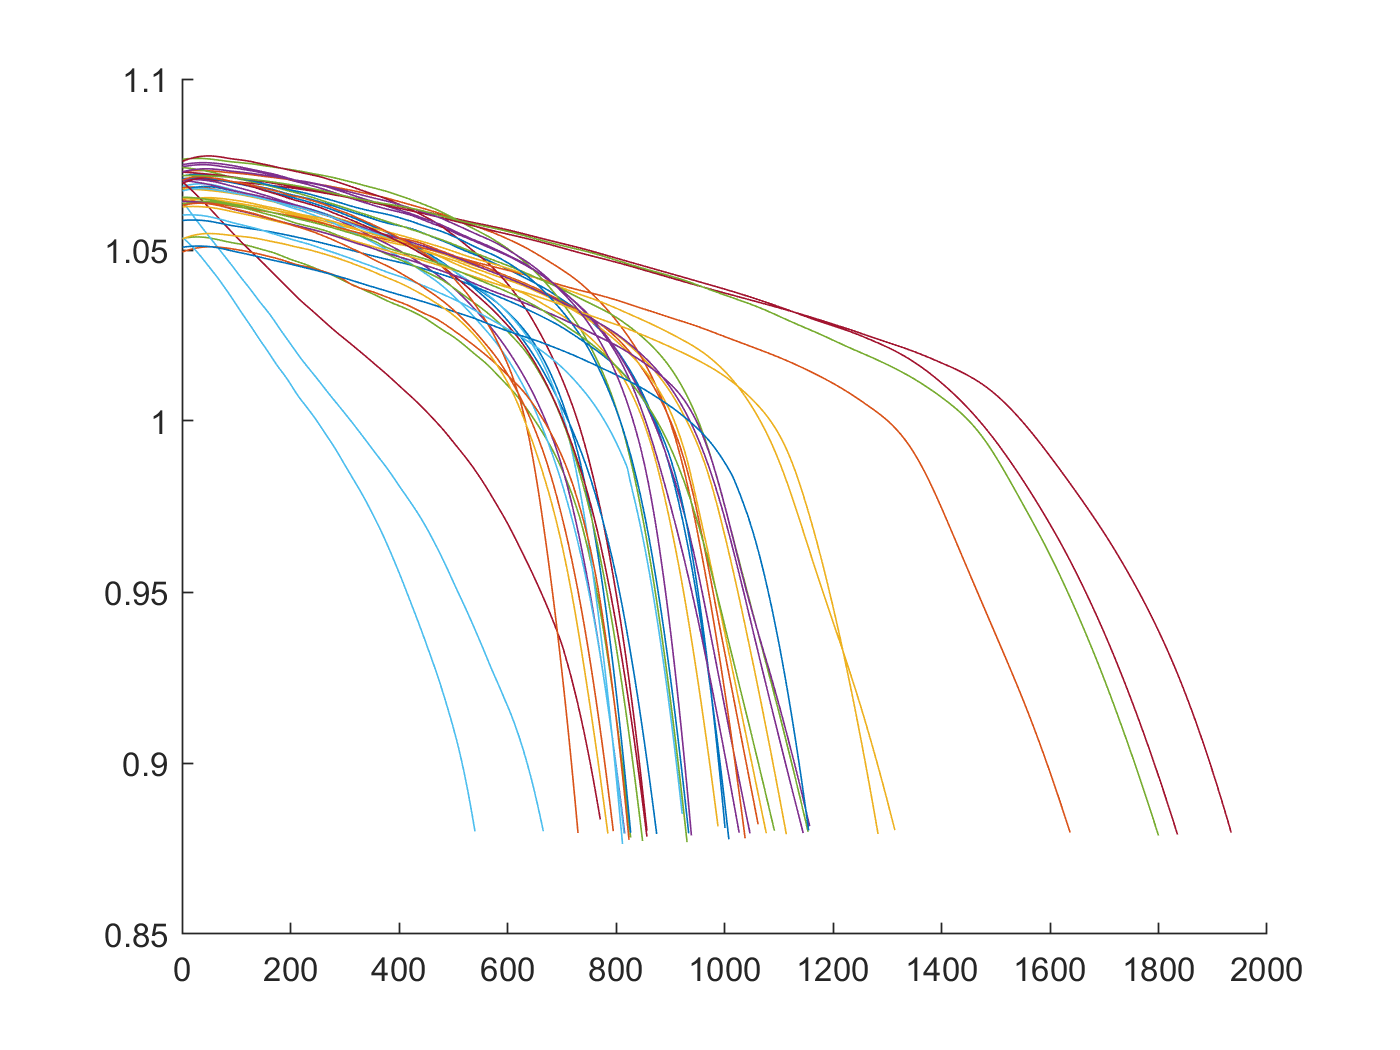

figure
hold on
for i=1:length(idx3)
    plot(battery_dataset(idx3(i)).QDischargeSmooth)
end
hold off

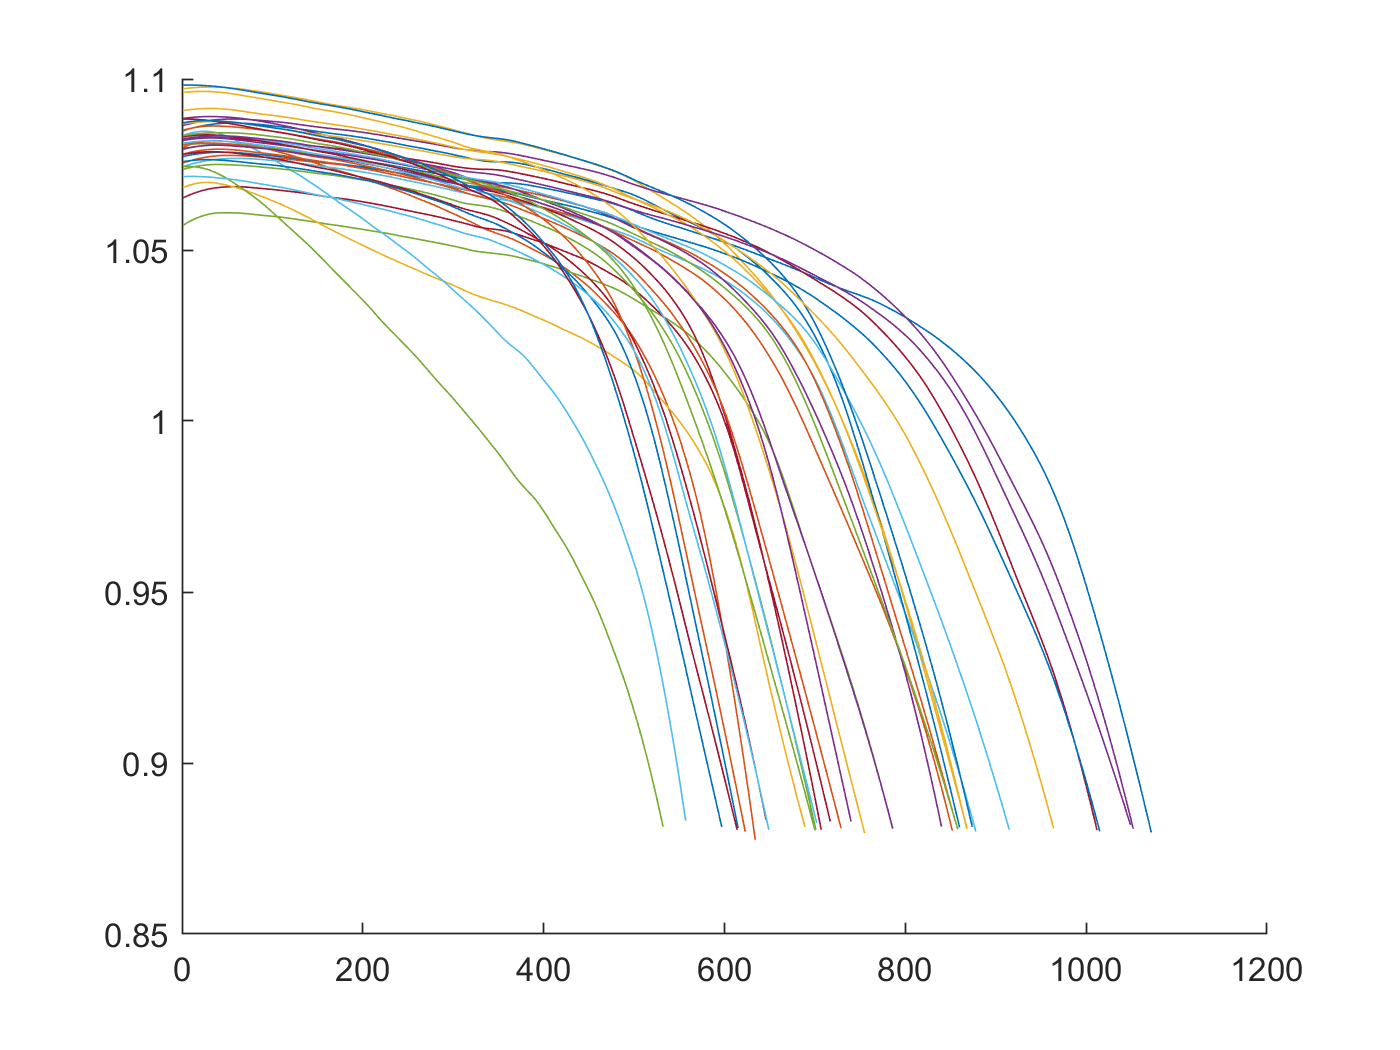


figure
hold on
for i=1:length(idx1)
    plot(battery_dataset(idx1(i)).QDischargeSmooth)
end
hold off

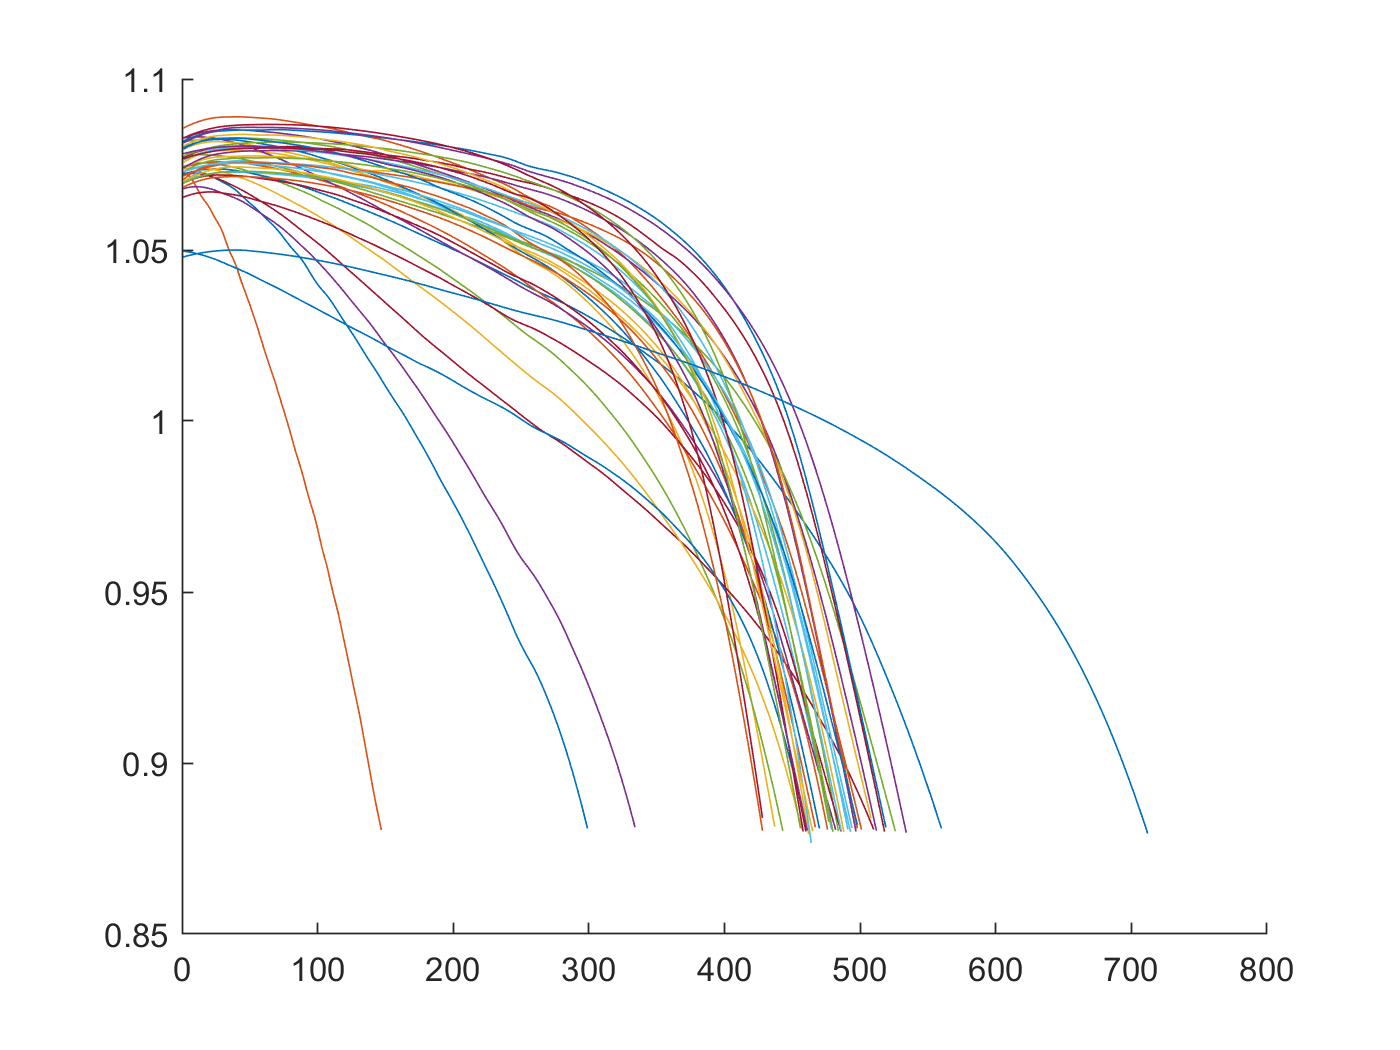


figure
hold on
for i=1:length(idx2)
    plot(battery_dataset(idx2(i)).QDischargeSmooth)
end
hold off


figure
hold on
for i=1:length(idx3)
    plot(battery_dataset(idx3(i)).QDischargeSmooth)
end
hold off

test dataset (batch1,2) 에서 값을 정규화하기

%idx = idxAll; %RMSE = 1032  - 잘 동작
idx = idx12 ; % training set - 잘 동작하지 않음
%idx = idx13 ; % training set - 잘 동작하지 않음
%idx = idx1;
key = [battery_dataset(idx).key]';
s = string([battery_dataset(idx).policy])

s = "4_4C-80PER_4_4C4_8C-80PER_4_8C4_8C-80PER_4_8C5_4C-40PER_3_6C5_4C-50PER_3C5_4C-60PER_3C5_4C-60PER_3C5_4C-60PER_3_6C5_4C-60PER_3_6C5_4C-70PER_3C5_4C-70PER_3C5_4C-80PER_5_4C5_4C-80PER_5_4C6C-30PER_3_6C6C-40PER_3C6C-40PER_3C6C-40PER_3_6C6C-40PER_3_6C6C-50PER_3C6C-50PER_3C6C-50PER_3_6C6C-50PER_3_6C6C-60PER_3C6C-60PER_3C7C-30PER_3_6C7C-30PER_3_6C7C-40PER_3C7C-40PER_3C7C-40PER_3_6C7C-40PER_3_6C8C-15PER_3_6C8C-15PER_3_6C8C-25PER_3_6C8C-25PER_3_6C8C-35PER_3_6C8C-35PER_3_6C1C_4PER_6C2C_10PER_6C2C_2PER_5C2C_7PER_5_5C3_6C_22PER_5_5C3_6C_2PER_4_85C3_6C_30PER_6C3_6C_9PER_5C4C_13PER_5C4C_31PER_54C_40PER_6C4C_4PER_4_85C4_4C_24PER_5C4_4C_47PER_5_5C4_4C_55PER_6C4_4C_8PER_4_85C4_65C_19PER_4_85C4_65C_44PER_5C4_65C_69PER_6C4_8C_80PER_4_8C4_8C_80PER_4_8C4_8C_80PER_4_8C4_9C_27PER_4_75C4_9C_61PER_4_5C4_9C_69PER_4_25C5_2C_10PER_4_75C5_2C_37PER_4_5C5_2C_50PER_4_25C5_2C_58PER_4C5_2C_66PER_3_5C5_2C_71PER_3C5_6C_25PER_4_5C5_6C_38PER_4_25C5_6C_47PER_4C5_6C_58PER_3_5C5_6C_5PER_4_75C5_6C_65PER_3C6C_20PER_4_5C6C_

s1 = string([{battery_dataset(idx).policy}])

s1 = 1×79 string array
    "4_4C-80PER_4_4C"    "4_8C-80PER_4_8C"    "4_8C-80PER_4_8C"    "5_4C-40PER_3_6C"    "5_4C-50PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3C"    "5_4C-60PER_3_6C"    "5_4C-60PER_3_6C"    "5_4C-70PER_3C"    "5_4C-70PER_3C"    "5_4C-80PER_5_4C"    "5_4C-80PER_5_4C"    "6C-30PER_3_6C"    "6C-40PER_3C"    "6C-40PER_3C"    "6C-40PER_3_6C"    "6C-40PER_3_6C"    "6C-50PER_3C"    "6C-50PER_3C"    "6C-50PER_3_6C"    "6C-50PER_3_6C"    "6C-60PER_3C"    "6C-60PER_3C"    "7C-30PER_3_6C"    "7C-30PER_3_6C"    "7C-40PER_3C"    "7C-40PER_3C"    "7C-40PER_3_6C"    "7C-40PER_3_6C"    "8C-15PER_3_6C"    "8C-15PER_3_6C"    "8C-25PER_3_6C"    "8C-25PER_3_6C"    "8C-35PER_3_6C"    "8C-35PER_3_6C"    "1C_4PER_6C"    "2C_10PER_6C"    "2C_2PER_5C"    "2C_7PER_5_5C"    "3_6C_22PER_5_5C"    "3_6C_2PER_4_85C"    "3_6C_30PER_6C"    "3_6C_9PER_5C"    "4C_13PER_5C"    "4C_31PER_5"    "4C_40PER_6C"    "4C_4PER_4_85C"    "4_4C_24PER_5C"    "4_4C_47PER_5_5C"    "4_4C_55PER_6C"    "4_4C_8PER_4_85

policy = [{battery_dataset(idx).policy}]';
policy_str = string([{battery_dataset(idx).policy}]');
policy_readable = [{battery_dataset(idx).policy_readable}]';
policy_readable_str = string([{battery_dataset(idx).policy_readable}]');
Ic1 = [{battery_dataset(idx).Ic}]';
Ic2 = [battery_dataset(idx).Ic];
Ic3 = reshape(Ic2,100,length(policy));
Ic = Ic3';
cycle = [battery_dataset(idx).cycle_life ]';
x=Ic;
y=cycle;
[ynorm,ymin,yrate,xnorm,xmin,xrate] = minmax_norm_new(y,x);

min(y)

ans = 147

max(y)

ans = 1072


yrate =  max(y) - min(y)

yrate = 925

ymin = min(y)

ymin = 147

ynorm = (y - ymin) / yrate

ynorm =     1.0000
    0.5265
    0.7795
    0.9784
    0.6908
    0.7903
    0.6162
    0.7708
    0.7654
    0.5859


yback = ynorm * yrate + ymin

yback =         1072
         634
         868
        1052
         786
         878
         717
         860
         855
         689


y

y =         1072
         634
         868
        1052
         786
         878
         717
         860
         855
         689


x

x =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999    4

min(min(x))

ans = 0

max(max(x))

ans = 8.0067

xrate =  max(max(x)) - min(min(x))

xrate = 8.0067

xmin = min(min(x))

xmin = 0

xnorm = (x - xmin) / xrate

xnorm =          0    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5496    0.5495    0.5495    0.5496    0.5496    0.5495    0.5496    0.5495    0.5495    0.5496    0.5496    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495    0.5495
         0    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5994    0.5995    0.5995    0.5994    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995    0.5995 

xback = xnorm * xrate + xmin

xback =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999 

x

x =          0    4.3999    4.3999    4.4000    4.4000    4.4001    4.3999    4.3999    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.3999    4.3999    4.3998    4.4000    4.3997    4.3998    4.3999    4.3997    4.3999    4.4005    4.3997    4.3994    4.4001    4.3999    4.3996    4.4007    4.4000    4.3997    4.4001    4.4002    4.3998    4.4003    4.4001    4.3999    4.4002    4.4002    4.4000    4.3999    4.3998    4.3999    4.3999    4.4000    4.3999    4.3999    4.4001    4.4001
         0    4.8000    4.7997    4.8001    4.8000    4.8002    4.8001    4.8003    4.8002    4.8001    4.8000    4.8000    4.8002    4.7994    4.7998    4.8000    4.7996    4.8001    4.8001    4.8000    4.8001    4.8000    4.8001    4.7998    4.7997    4.7997    4.7998    4.7997    4.8000    4.7998    4.7999    4.8002    4.7999    4.8000    4.8001    4.8000    4.8000    4.8000    4.8000    4.8001    4.8002    4.7999    4.8000    4.7999    4.8001    4.8001    4.8000    4.7998    4.7999    4